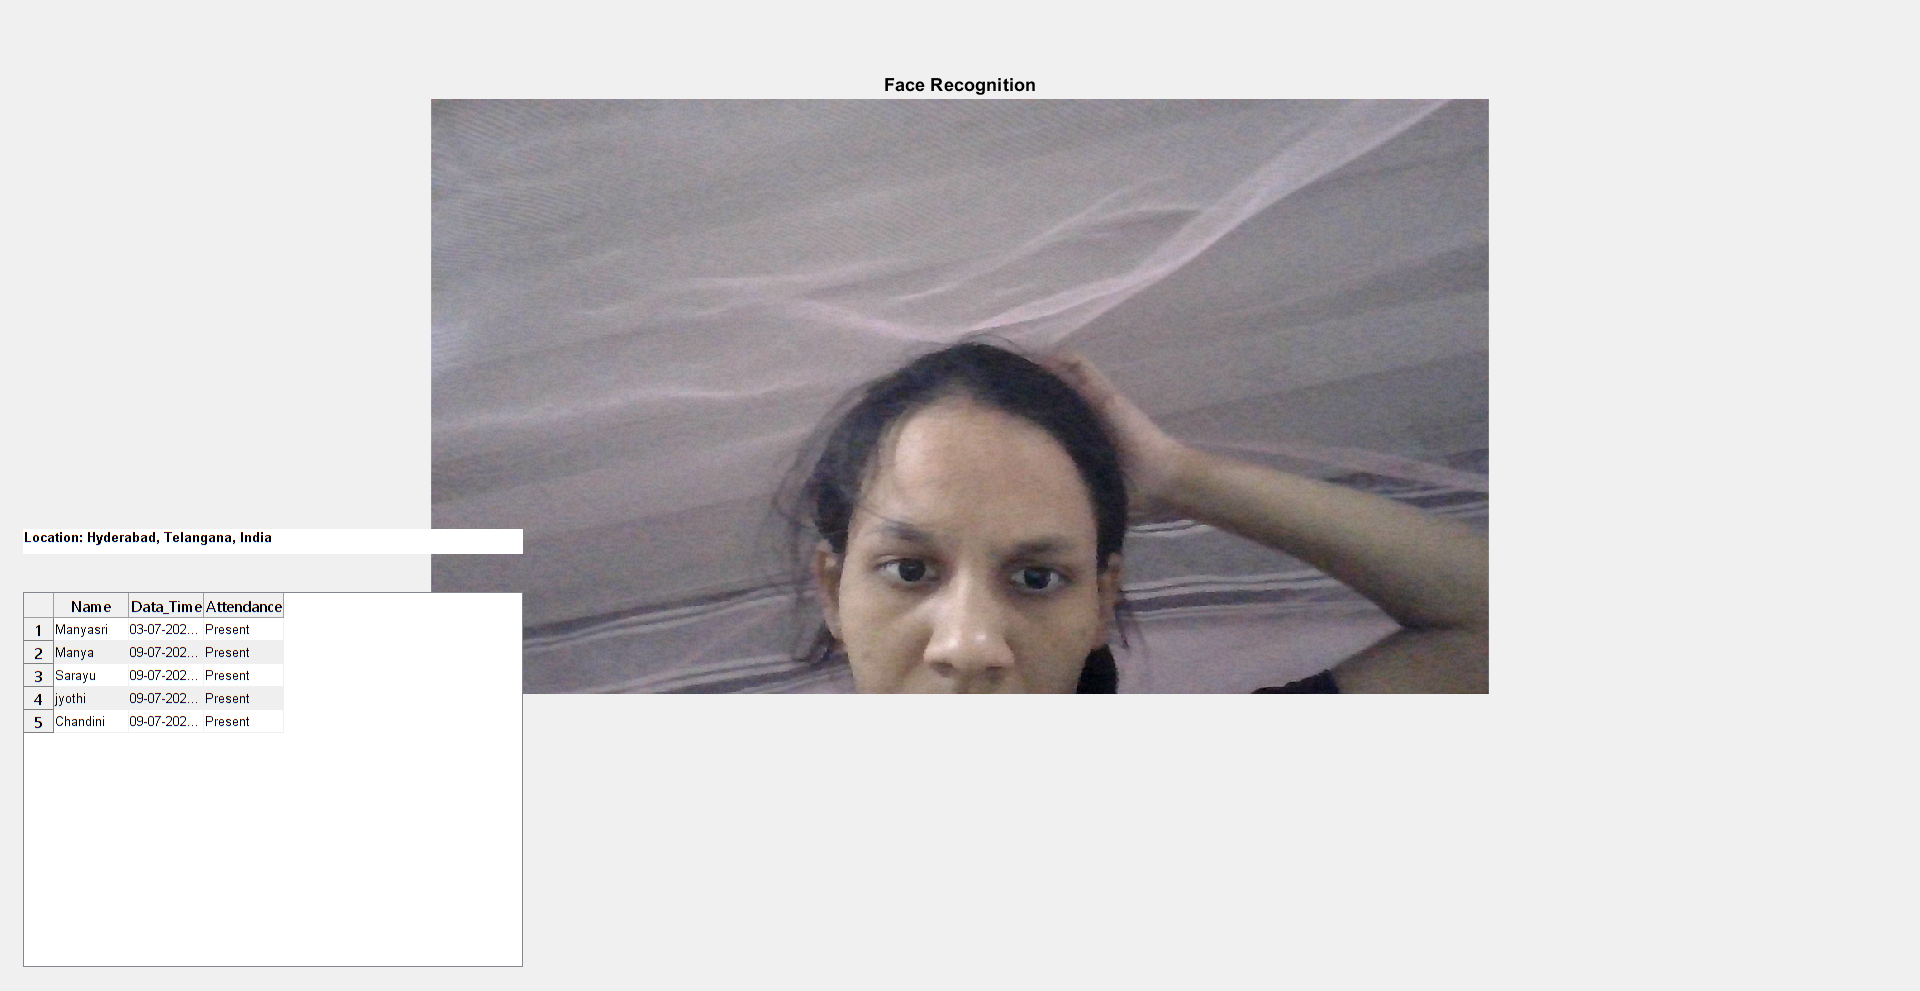

clc;
close all;
clear;

% Initialize webcam and necessary objects
c = webcam;
load myNet1; % Load your pretrained network
faceDetector = vision.CascadeObjectDetector;

% Excel file setup
excelFile = 'attendance.xlsx';
sheetName = 'Sheet1';

% Check if the file exists, if not, create it with headers
if ~isfile(excelFile)
    headers = {'Name', 'Time', 'Present', 'Latitude', 'Longitude', 'Area'};
    writetable(cell2table(cell(0, 6), 'VariableNames', headers), excelFile, 'Sheet', sheetName);
end

% Read existing names from the Excel file to avoid duplicates
try
    T = readtable(excelFile, 'Sheet', sheetName, 'ReadVariableNames', true);
    existingNames = unique(T.Name);
catch
    T = table();
    existingNames = {};
end

% Initialize figure and table
f = figure('Name', 'Attendance Sheet', 'NumberTitle', 'off');
t = uitable('Parent', f, 'Position', [20 20 400 300]);

% Create axes for displaying the image
ax = axes('Parent', f, 'Position', [0.05 0.3 0.9 0.6]);

% Text box for displaying location
locationTextBox = uicontrol('Style', 'text', 'Position', [20 350 400 20], 'String', 'Location: Retrieving...', ...
    'HorizontalAlignment', 'left', 'BackgroundColor', 'white', 'FontWeight', 'bold');

% Directory to save captured images
imageDir = 'captured_images';
if ~isfolder(imageDir)
    mkdir(imageDir);
end

% Function to get current location using an IP-based geolocation API
function [latitude, longitude, area] = getCurrentLocation()
    url = 'http://ip-api.com/json';
    latitude = NaN;
    longitude = NaN;
    area = '';
    
    try
        data = webread(url);
        latitude = data.lat;
        longitude = data.lon;
        area = sprintf('%s, %s, %s', data.city, data.regionName, data.country);
    catch
        warning('Could not retrieve location data.');
    end
end

% Main loop to capture webcam and perform face recognition
while ishandle(f)
    % Get current location
    [latitude, longitude, area] = getCurrentLocation();
    
    % Update location text box
    if ~isnan(latitude) && ~isnan(longitude)
        locationText = sprintf('Location: %s', area);
    else
        locationText = 'Location: Unknown';
    end
    set(locationTextBox, 'String', locationText);
    
    % Capture frame from webcam
    e = snapshot(c);
    
    % Detect faces in the frame
    bboxes = step(faceDetector, e);
    
    % Initialize labelStr
    labels = cell(size(bboxes, 1), 1);
    
    % Define a threshold for classification confidence
    threshold = 0.6; % Adjust as needed
    
    % Process each detected face
    for i = 1:size(bboxes, 1)
        % Extract and preprocess face image
        es = imcrop(e, bboxes(i,:));
        es = imresize(es, [227 227]);
        
        % Classify the face using pretrained network
        [label, score] = classify(myNet1, es);
        
        % Apply threshold to classification
        if max(score) < threshold
            labelStr = 'Unknown Image';
        else
            labelStr = char(label);
        end
        
        % Check if the label is recognized and in the database
        if strcmp(labelStr, 'Unknown Image') || ~ismember(labelStr, existingNames)
            % If new entry or unknown
            if ~strcmp(labelStr, 'Unknown Image') && ~ismember(labelStr, existingNames)
                % Record current time
                currentTime = datestr(now, 'dd-mm-yyyy HH:MM:SS');
                
                % Add new entry to the table and write to Excel file
                newEntry = {labelStr, currentTime, 'Present', num2str(latitude), num2str(longitude), area};
                T = [T; newEntry];
                writetable(T, excelFile, 'Sheet', sheetName);
                
                % Update existing names list
                existingNames = [existingNames; labelStr];
                
                % Save captured image with unique filename
                filename = fullfile(imageDir, sprintf('%s_%s.bmp', labelStr, datestr(now, 'yyyymmddHHMMSS')));
                imwrite(es, filename);
            end
        end
        
        % Annotate as "Unknown" above the name if not recognized
        if strcmp(labelStr, 'Unknown Image')
            labelStr = sprintf('Unknown\n%s', labelStr);
        end
        
        labels{i} = labelStr; % Store label for annotation
    end
    
    % Update table display
    if ~isempty(T)
        t.Data = T{:,:};
        t.ColumnName = T.Properties.VariableNames;
    end
    
    % Display the frame with detected face annotations
    if ~isempty(bboxes)
        e = insertObjectAnnotation(e, 'rectangle', bboxes, labels);
    end
    imshow(e, 'Parent', ax); % Display image in the axes
    title(ax, 'Face Recognition'); % Set title on the axes
    drawnow;
end


% Cleanup
clear c;
